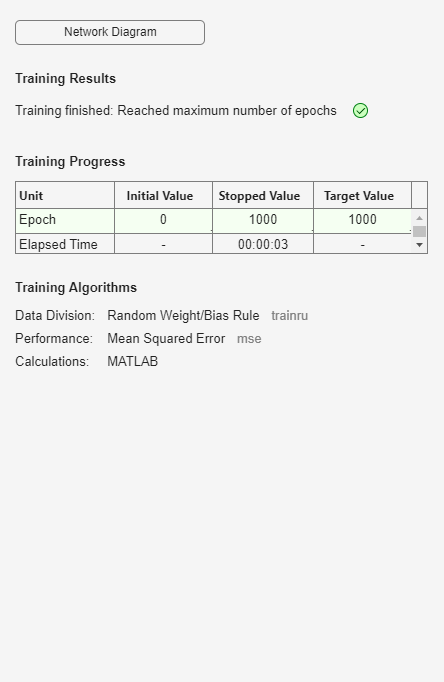

%竞争型网络（无目标分类）
%福冈与中国城市分类（标准化数据）
clear                                       %清理内存
P=[-1.0972 -0.5551 0.2582 1.7039 0.8907 -0.5551 -0.6454 
-1.2094 -0.3634 0.1092 1.4278 0.9143 -1.1919 0.3134 
1.1834 0.7953 -0.3282 -0.3814 0.0536 -1.8522 0.5293 
-1.6362 -1.1296 0.0680 0.7742 0.8357 0.8203 0.2676 
-1.4575 -1.0634 -0.2752 1.2135 0.9946 0.1626 0.4254];
net=newc(minmax(P),2);                      %创建一个五变量二分类的竞争型网络
net.trainParam.epochs=1000;                 %指定最大训练次数
net=train(net,P);                           %训练网络

Y=sim(net,P)                                %仿真结果

Y =      1     1     1     0     0     0     1
     0     0     0     1     1     1     0


Yc=vec2ind(Y)                               %输出分类向量

Yc =      1     1     1     2     2     2     1
